Initialize Symbolics

syms x_1 x_2 x_3 phi theta psi v_1 v_2 v_3 omega_1 omega_2 omega_3 
syms g m l sigma c1 c2 c3 r1 r2 r3 e1 e2 e3 I_x I_y I_z
syms phi theta psi u_1 u_2 u_3 u_4 

Create given matrices and initialize variables\

R_ce=[cos(theta)*cos(psi) sin(phi)*sin(theta)*cos(psi)-cos(phi)*sin(psi) sin(phi)*sin(psi)+cos(phi)*sin(theta)*cos(psi);
    cos(theta)*sin(psi) cos(phi)*cos(psi)+sin(phi)*sin(theta)*sin(psi) cos(phi)*sin(theta)*sin(psi)-sin(phi)*cos(psi);
    -sin(theta) sin(phi)*cos(theta) cos(phi)*cos(theta)];
T_inv=[1 sin(phi)*tan(theta) cos(phi)*tan(theta);
    0 cos(phi) -sin(phi);
    0 sin(phi)/cos(theta) cos(phi)/cos(theta)];
omega=[omega_1; omega_2; omega_3];
x=[x_1; x_2; x_3];
v=[v_1; v_2; v_3];
alpha=[phi; theta; psi];


e1=[1; 0; 0];
e2=[0; 1; 0];
e3=[0; 0; 1];

c1=[1; 0; 0];
c2=[0; 1; 0];
c3=[0; 0; 1];

n=[0; 0; 0];
r=[0; 0; 0];

I=[I_x 0 0;
    0 I_y 0;
    0 0 I_z];

Create the state variable

z=[x_1; x_2; x_3; phi; theta; psi; v_1; v_2; v_3; omega_1; omega_2; omega_3]

$$z = \left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3}\\ \varphi \\ \theta \\ \psi \\ v_{1}\\ v_{2}\\ v_{3}\\ \omega_{1}\\ \omega_{2}\\ \omega_{3} \end{array}\right)$$

u=[u_1; u_2; u_3; u_4]

$$u = \left(\begin{array}{c} u_{1}\\ u_{2}\\ u_{3}\\ u_{4} \end{array}\right)$$

Set up the equations

xdot=v

$$xdot = \left(\begin{array}{c} v_{1}\\ v_{2}\\ v_{3} \end{array}\right)$$

alphadot=simplify(T_inv*omega)

$$alphadot = \left(\begin{array}{c} \omega_{1}+\omega_{3}\,\cos\left(\varphi \right)\,\tan\left(\theta \right)+\omega_{2}\,\sin\left(\varphi \right)\,\tan\left(\theta \right)\\ \omega_{2}\,\cos\left(\varphi \right)-\omega_{3}\,\sin\left(\varphi \right)\\ \frac{\omega_{3}\,\cos\left(\varphi \right)+\omega_{2}\,\sin\left(\varphi \right)}{\cos\left(\theta \right)} \end{array}\right)$$

vdot=simplify(-g*e3+1/m*(R_ce*(u_1+u_2+u_3+u_4)*c3+1/m*R_ce*r))

$$vdot = \left(\begin{array}{c} \frac{\left(\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\right)\,\left(u_{1}+u_{2}+u_{3}+u_{4}\right)}{m}\\ -\frac{\left(\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right)\,\left(u_{1}+u_{2}+u_{3}+u_{4}\right)}{m}\\ \frac{\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\left(u_{1}+u_{2}+u_{3}+u_{4}\right)}{m}-g \end{array}\right)$$

omegadot=simplify(inv(I)*((u_2-u_4)*l*c1+(u_3-u_1)*l*c2+(u_1-u_2+u_3-u_4)*sigma*c3+n-cross(omega,I*omega)))

$$omegadot = \left(\begin{array}{c} \frac{l\,\left(u_{2}-u_{4}\right)+I_{y}\,\omega_{2}\,\omega_{3}-I_{z}\,\omega_{2}\,\omega_{3}}{I_{x}}\\ -\frac{l\,\left(u_{1}-u_{3}\right)+I_{x}\,\omega_{1}\,\omega_{3}-I_{z}\,\omega_{1}\,\omega_{3}}{I_{y}}\\ \frac{\sigma \,\left(u_{1}-u_{2}+u_{3}-u_{4}\right)+I_{x}\,\omega_{1}\,\omega_{2}-I_{y}\,\omega_{1}\,\omega_{2}}{I_{z}} \end{array}\right)$$


zdot=[xdot;alphadot;vdot;omegadot]

$$zdot = \left(\begin{array}{c} v_{1}\\ v_{2}\\ v_{3}\\ \omega_{1}+\omega_{3}\,\cos\left(\varphi \right)\,\tan\left(\theta \right)+\omega_{2}\,\sin\left(\varphi \right)\,\tan\left(\theta \right)\\ \omega_{2}\,\cos\left(\varphi \right)-\omega_{3}\,\sin\left(\varphi \right)\\ \frac{\omega_{3}\,\cos\left(\varphi \right)+\omega_{2}\,\sin\left(\varphi \right)}{\cos\left(\theta \right)}\\ \frac{\left(\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\right)\,\left(u_{1}+u_{2}+u_{3}+u_{4}\right)}{m}\\ -\frac{\left(\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right)\,\left(u_{1}+u_{2}+u_{3}+u_{4}\right)}{m}\\ \frac{\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\left(u_{1}+u_{2}+u_{3}+u_{4}\right)}{m}-g\\ \frac{l\,\left(u_{2}-u_{4}\right)+I_{y}\,\omega_{2}\,\omega_{3}-I_{z}\,\omega_{2}\,\omega_{3}}{I_{x}}\\ -\frac{l\,\left(u_{1}-u_{3}\right)+I_{x}\,\omega_{1}\,\omega_{3}-I_{z}\,\omega_{1}\,\omega_{3}}{I_{y}}\\ \frac{\sigma \,\left(u_{1}-u_{2}+u_{3}-u_{4}\right)+I_{x}\,\omega_{1}\,\omega_{2}-I_{y}\,\omega_{1}\,\omega_{2}}{I_{z}} \end{array}\right)$$

Part A

phi=0;
theta=0;
psi=0;
v_1=0;
v_2=0;
v_3=0;
omega_1=0;
omega_2=0;
omega_3=0;
u_1=m*g/4;
u_2=m*g/4;
u_3=m*g/4;
u_4=m*g/4;


Part B

Zdot=eval(zdot)

$$Zdot = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

A=[];
f=jacobian(zdot,z)

for i=1:12
    dfdz=gradient(zdot(i),z).';
    A=[A;dfdz];
end
A1=eval(A)

$$A1 = \left(\begin{array}{cccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & g & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & -g & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

B=[];
for i=1:12
    dfdu=gradient(zdot(i),u).';
    B=[B;dfdu];
end
B1=eval(B)

$$B1 = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ \frac{1}{m} & \frac{1}{m} & \frac{1}{m} & \frac{1}{m}\\ 0 & \frac{l}{I_{x}} & 0 & -\frac{l}{I_{x}}\\ -\frac{l}{I_{y}} & 0 & \frac{l}{I_{y}} & 0\\ \frac{\sigma }{I_{z}} & -\frac{\sigma }{I_{z}} & \frac{\sigma }{I_{z}} & -\frac{\sigma }{I_{z}} \end{array}\right)$$

Part C

C=[B1 A1*B1 A1^2*B1 A1^3*B1 A1^4*B1 A1^5*B1 A1^6*B1 A1^7*B1 A1^8*B1 A1^9*B1 A1^10*B1 A1^11*B1];
Rank=rank(C);

So the error dynamic is controllable

Q=eye(12)

Q =      1     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0


R=eye(4)

R =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


m=1

m = 1

l=.2

l = 0.2000

g=9.81

g = 9.8100

sigma=.01

sigma = 0.0100

I_x=1.24

I_x = 1.2400

I_y=1.24

I_y = 1.2400

I_z=1.24

I_z = 1.2400

A=subs(A1)

$$A = \left(\begin{array}{cccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & \frac{981}{100} & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & -\frac{981}{100} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

B=subs(B1)

$$B = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1 & 1 & 1 & 1\\ 0 & \frac{5}{31} & 0 & -\frac{5}{31}\\ -\frac{5}{31} & 0 & \frac{5}{31} & 0\\ \frac{1}{124} & -\frac{1}{124} & \frac{1}{124} & -\frac{1}{124} \end{array}\right)$$

A=double(A)

A =          0         0         0         0         0         0    1.0000         0         0         0         0         0
         0         0         0         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0         0         0         0    1.0000         0         0         0
         0         0         0         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0         0         0         0         0         0    1.0000
         0         0         0         0    9.8100         0         0         0         0         0         0         0
         0         0         0   -9.8100         0         0         0         0         0         0         0         0
         0         0        

B=double(B)

B =          0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    1.0000    1.0000    1.0000    1.0000
         0    0.1613         0   -0.1613


K=lqr(A,B,Q,R)

K =    -0.7071    0.0000    0.5000   -0.0000  -17.9388    0.5000   -1.7567    0.0000    0.7071   -0.0000  -10.5698    5.5902
    0.0000   -0.7071    0.5000   17.9388    0.0000   -0.5000    0.0000   -1.7567    0.7071   10.5698    0.0000   -5.5902
    0.7071   -0.0000    0.5000    0.0000   17.9388    0.5000    1.7567   -0.0000    0.7071   -0.0000   10.5698    5.5902
   -0.0000    0.7071    0.5000  -17.9388   -0.0000   -0.5000   -0.0000    1.7567    0.7071  -10.5698   -0.0000   -5.5902


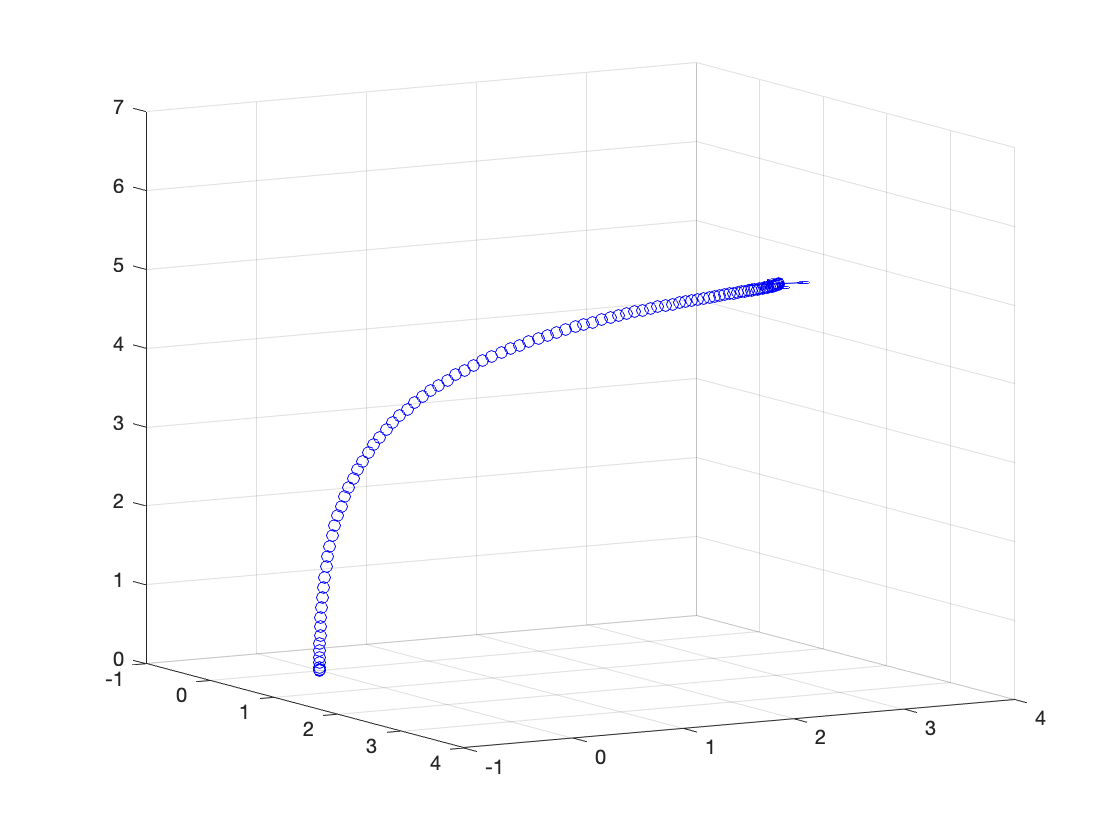

e0=[2;3;5;0;0;pi;0;0;0;0;0;0];
tspan=linspace (0,5);
[t,et]=ode45(@(t,et) (A-B*K)*et,tspan,e0);
f=figure;
gif('demo.gif')
for i=1:length(t)
    xt=transpose(e0-transpose(et(i,:)));
    CopterHandles=PlotCopter([xt(1),xt(2),xt(3)],xt(4),xt(5),xt(6),[0,0,1]);
    %view(26+15*x,29-10*x)
    gif
    pause(.5);
    if i<length(t) 
        for j=1:length(CopterHandles)
            delete(CopterHandles(j));
        end
    end
end

function h=plotCircle3D(center,normal,radius, C)
    %this fuction plots a circle given a center, tradius and the normal vector.
    %center and normal are ROW vector
    theta=0:0.01:2*pi;
    v=null(normal);
    points=repmat(center',1,size(theta,2))+radius*(v(:,1)*cos(theta)+v(:,2)*sin(theta));
    h=plot3(points(1,:),points(2,:),points(3,:),'-', 'Color', C);
end

function h_copter=PlotCopter(cm, roll, pitch, yaw, C)

%this function draws the quadrotor.  Need to have it return the handles for cleanup.

    h_copter=[];
    l=.2;
    r=.05;
    z=[0;0;1];
    I3=eye(3);
    R=rotate(roll, pitch, yaw) ;
    norm=transpose(R*z);
   %the base quad setup at zero
    LF0=[l*cos(pi/4);l*sin(pi/4);0];
    LR0=[l*cos(3*pi/4);l*sin(3*pi/4);0];
    RR0=[l*cos(5*pi/4);l*sin(5*pi/4);0];
    RF0=[l*cos(7*pi/4);l*sin(7*pi/4);0];
    
   %Quad rotated through R matrix
    LF=[cm;[cm+transpose(R*LF0)]];
    LR=[cm;[cm+transpose(R*LR0)]];
    RR=[cm;[cm+transpose(R*RR0)]];
    RF=[cm;[cm+transpose(R*RF0)]];
    
   %plotting
    plot3(cm(1),cm(2), cm(3),"o", 'Color',C);
    view(60,10)
    grid on
    xlim([-1,4])
    ylim([-1,4])
    zlim([0,7])
    hold on;
    h_copter=[h_copter;plot3(LF(:,1), LF(:,2),LF(:,3),"-", 'Color',C)];
    h_copter=[h_copter;plotCircle3D(LF(2,:), norm,r,C)];
    h_copter=[h_copter;plot3(LR(:,1), LR(:,2),LR(:,3),"-", 'Color',C)];
    h_copter=[h_copter;plotCircle3D(LR(2,:),norm,r,C)];
    h_copter=[h_copter;plot3(RR(:,1), RR(:,2),RR(:,3),"-", 'Color',C)];
    h_copter=[h_copter;plotCircle3D(RR(2,:), norm,r,C)];
    h_copter=[h_copter;plot3(RF(:,1), RF(:,2),RF(:,3),"-", 'Color',C)];
    h_copter=[h_copter;plotCircle3D(RF(2,:), norm,r,C)];
    %hold off;
end

function R=rotate(phi, theta, psi) % to give R matrix with roll pitch yaw angles
    R=[cos(theta)*cos(psi) sin(phi)*sin(theta)*cos(psi)-cos(phi)*sin(psi) sin(phi)*sin(psi)+cos(phi)*sin(theta)*cos(psi);
    cos(theta)*sin(psi) cos(phi)*cos(psi)+sin(phi)*sin(theta)*sin(psi) cos(phi)*sin(theta)*sin(psi)-sin(phi)*cos(psi);
    -sin(theta) sin(phi)*cos(theta) cos(phi)*cos(theta)];
end

function gif(varargin)
%Greene, Chad A., et al. "The Climate Data Toolbox for MATLAB.” 
%Geochemistry, Geophysics, Geosystems, vol. 20, no. 7, 
%American Geophysical Union (AGU), July 2019, pp. 3774–81, doi:10.1029/2019gc008392.
% gif is the simplest way to make gifs. Simply call
% 
%   gif('myfile.gif') 
% 
% to write the first frame, and then call 
% 
%   gif
% 
% to write each subsequent frame. That's it. 
% 
%% Syntax
% 
%  gif('filename.gif') 
%  gif(...,'DelayTime',DelayTimeValue,...) 
%  gif(...,'LoopCount',LoopCountValue,...) 
%  gif(...,'frame',handle,...) 
%  gif(...,'resolution',res)
%  gif(...,'nodither') 
%  gif(...,'overwrite',true)
%  gif 
%  gif('clear') 
% 
%% Description 
% 
% gif('filename.gif') writes the first frame of a new gif file by the name filename.gif. 
% 
% gif(...,'DelayTime',DelayTimeValue,...) specifies a the delay time in seconds between
% frames. Default delay time is 1/15. 
% 
% gif(...,'LoopCount',LoopCountValue,...) specifies the number of times the gif animation 
% will play. Default loop count is Inf. 
% 
% gif(...,'frame',handle,...) uses the frame of the given figure or set of axes. The default 
% frame handle is gcf, meaning the current figure. To turn just one set of axes into a gif, 
% use 'frame',gca. This behavior changed in Jan 2021, as the default option changed from
% gca to gcf.
% 
% gif(...,'resolution',res) specifies the resolution (in dpi) of each frame. This option
% requires export_fig (https://www.mathworks.com/matlabcentral/fileexchange/23629).
%
% gif(...,'nodither') maps each color in the original image to the closest color in the new 
% without dithering. Dithering is performed by default to achieve better color resolution, 
% albeit at the expense of spatial resolution.
% 
% gif(...,'overwrite',true) bypasses a dialoge box that would otherwise verify 
% that you want to overwrite an existing file by the specified name. 
%
% gif adds a frame to the current gif file. 
% 
% gif('clear') clears the persistent variables associated with the most recent gif. 
% 
%% Example 
% For examples, type 
% 
%   cdt gif
% 
%% Author Information 
% This function was written by Chad A. Greene of the University of Texas 
% Institute for Geophysics (UTIG), June 2017. 
% 
% See also: imwrite, getframe, and rgb2ind. 
% Define persistent variables: 
persistent gif_filename firstframe DelayTime DitherOption LoopCount frame resolution
%% Parse Inputs
if nargin>0 
   
   % The user may want to clear things and start over: 
   if any(strcmpi(varargin,'clear'))
            
      % Clear persistent variables associated with this function: 
      clear gif_filename firstframe DelayTime DitherOption LoopCount frame resolution
   end
   
   % If the first input ends in .gif, assume this is the first frame:
   if strcmpi(varargin{1}(end-3:end),'.gif')
      
      % This is what the user wants to call the new .gif file: 
      gif_filename = varargin{1}; 
      
      % Check for an existing .gif file by the same name: 
      if exist(gif_filename,'file')==2
         OverWrite = false; % By default, do NOT overwrite an existing file by the input name. 
         if nargin>1
            tmp = strncmpi(varargin,'overwrite',4); 
            if any(tmp)
               OverWrite = varargin{find(tmp)+1}; 
               assert(islogical(OverWrite),'Error: Overwrite input must be either true or false.')
            end
         end
         
         if ~OverWrite
         
            % Ask the user if (s)he wants to overwrite the existing file: 
            choice = questdlg(['The file  ',gif_filename,' already exists. Overwrite it?'], ...
               'The file already exists.','Overwrite','Cancel','Cancel');
            if strcmp(choice,'Overwrite')
               OverWrite = true; 
            end
         end
         
         % Overwriting basically means deleting and starting from scratch: 
         if OverWrite
            delete(gif_filename) 
         else 
            clear gif_filename firstframe DelayTime DitherOption LoopCount frame
            error('The giffing has been canceled.') 
         end
         
      end
      
      firstframe = true; 
      
      % Set defaults: 
      DelayTime = 1/15; 
      DitherOption = 'dither'; 
      LoopCount = Inf; 
      frame = gcf; 
      resolution = 0; % When 0, it's used as a boolean to say "don't use export_fig". If greater than zero, the boolean says "use export_fig and use the specified resolution."  
   end
   
   tmp = strcmpi(varargin,'DelayTime'); 
   if any(tmp) 
      DelayTime = varargin{find(tmp)+1}; 
      assert(isscalar(DelayTime),'Error: DelayTime must be a scalar value.') 
   end
   
   if any(strcmpi(varargin,'nodither'))
      DitherOption = 'nodither'; 
   end
   
   tmp = strcmpi(varargin,'LoopCount'); 
   if any(tmp) 
      LoopCount = varargin{find(tmp)+1}; 
      assert(isscalar(LoopCount),'Error: LoopCount must be a scalar value.') 
   end
   
   tmp = strncmpi(varargin,'resolution',3); 
   if any(tmp) 
      resolution = varargin{find(tmp)+1}; 
      assert(isscalar(resolution),'Error: resolution must be a scalar value.') 
      assert(exist('export_fig.m','file')==2,'export_fig not found. If you wish to specify the image resolution, get export_fig here :https://www.mathworks.com/matlabcentral/fileexchange/23629. Otherwise remove the resolution from the gif inputs to use the default (lower quality) built-in getframe functionality.')  
      warning off export_fig:exportgraphics
   end
   
   tmp = strcmpi(varargin,'frame'); 
   if any(tmp) 
      frame = varargin{find(tmp)+1}; 
      assert(ishandle(frame)==1,'Error: frame must be a figure handle or axis handle.') 
   end
   
else
   assert(isempty(gif_filename)==0,'Error: The first call of the gif function requires a filename ending in .gif.') 
end
%% Perform work: 
if resolution % If resolution is >0, it means use export_fig
   
   if isgraphics(frame,'figure')
      f = export_fig('-nocrop',['-r',num2str(resolution)]);
   else
      % If the frame is a set of axes instead of a figure, use default cropping: 
      f = export_fig(['-r',num2str(resolution)]);
   end
      
else
   % Get frame: 
   fr = getframe(frame); 
   f =  fr.cdata; 
end
% Convert the frame to a colormap and corresponding indices: 
[imind,cmap] = rgb2ind(f,256,DitherOption);    
% Write the file:     
if firstframe
   imwrite(imind,cmap,gif_filename,'gif','LoopCount',LoopCount,'DelayTime',DelayTime)
   firstframe = false;
else
   imwrite(imind,cmap,gif_filename,'gif','WriteMode','append','DelayTime',DelayTime)
end
end
